## The confirmation GPR is correct or not

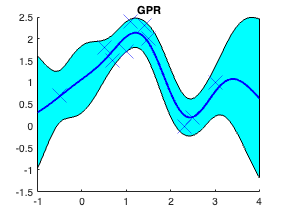

% 姿勢，軌道を状態変数(変数７個？)に持つGPR
clc
clear
close all
dir = pwd;
% addpath(strcat(dir, ''))

% kernel parameters
tau = log(1);
sigma = log(1);
eta = log(0.1);
params = [tau sigma eta];

% 学習データ読み込み
% % (from yoshimulibrary...)
% D_p = readmatrix('train_data_using_yoshimulibrary/D_p001.csv');
% t_mApp = readmatrix('train_data_using_yoshimulibrary/t_mApp001.csv');
% % 入力の学習データ
% xtrain = D_p(:,1:7);
% q0_train = D_p(:,1,:); q1_train = D_p(:,2,:); q2_train = D_p(:,3,:); q3_train = D_p(:,4,:);
% w1_train = D_p(:,5,:); w2_train = D_p(:,6,:); w3_train = D_p(:,7,:);
% % 出力の学習データ
% ytrain = D_p(:,8:14);
% delta_q0_train = D_p(:,1,:); delta_q1_train = D_p(:,2,:); delta_q2_train = D_p(:,3,:); delta_q3_train = D_p(:,4,:);
% delta_w1_train = D_p(:,5,:); delta_w2_train = D_p(:,6,:); delta_w3_train = D_p(:,7,:);
% 
% t_train = t_mApp(1:(length(t_mApp) - 1), 1);
data = readmatrix('gpr.dat');
xtrain = zeros(length(data), 1); ytrain = zeros(length(data), 1);
for i = 1:1:length(data)
    xtrain(i,1) = data(i,1);
    ytrain(i,1) = data(i,2);
end

% 確め計算ゾーン ------------------------------------------------------------
gaussian_kernel(xtrain(2,:), xtrain(3,:), params);
kv(xtrain(2,:), xtrain, params);
% kernel_matrix()

% -------------------------------------------------------------------------

% カーネル行列のハイパーパラメータ推定
% params = optimize1(params, xtrain, ytrain);

% 回帰の計算
% testData = readmatrix('train_data_using_yoshimulibrary/D_p002.csv'); % テストデータの入力？
% xx = testData(:, 1:7);
xx = (-1:0.01:4)';
N = length(xx); % これがあってるかわからん
yy_mu = zeros(N, length(xx(1,:))); yy_var = zeros(N, length(xx(1,:)));
for i = 1:1:length(ytrain(1,:))
    regression = gpr(xx, xtrain, ytrain(:,i), params); % length(xx)行2列？
    yy_mu(:,i) = regression(:,1); yy_var(:,i) = regression(:,2); 
end
two_sigma1 = yy_mu - 2 * sqrt(yy_var); two_sigma2 = yy_mu + 2 * sqrt(yy_var);

% plot --------------------------------------------------------------------
f1 = figure; % f2 = figure; f3 = figure; f4 = figure; f5 = figure; f6 = figure; f7 = figure;

figure(f1)
patch([xx', fliplr(xx')], [two_sigma1', fliplr(two_sigma2')], 'c');
hold on;
plot(xtrain, ytrain, 'bx', MarkerSize=20);
hold on;
plot(xx, yy_mu, 'b-', LineWidth=2);
title("GPR");
save_name = "gpr.png";
saveas(gcf, save_name);



% figure(f1);
% % patch([xx(:,1)', fliplr(xx(:,1)')], [two_sigma1', fliplr(two_sigma2')], 'c');
% % hold on;
% plot(xtrain(:,1), ytrain(:,1), 'k.', MarkerSize=10); % 学習データ
% hold on;
% plot(xx(:,1), testData(:,8), 'r.'); % 真値？
% hold on;
% plot(xx(:,1), yy_mu(:,1), 'b.', LineWidth=2); % 回帰結果？
% title("q0");
% 
% figure(f2);
% plot(xtrain(:,2), ytrain(:,2), 'k.', MarkerSize=10); % 学習データ
% hold on;
% plot(xx(:,2), testData(:,9), 'r.'); % 真値？
% hold on;
% plot(xx(:,2), yy_mu(:,2), 'b.'); % 回帰結果？
% title("q1");
% 
% figure(f3);
% plot(xtrain(:,3), ytrain(:,3), 'k.', MarkerSize=10); % 学習データ
% hold on;
% plot(xx(:,3), testData(:,10), 'r.'); % 真値？
% hold on;
% plot(xx(:,3), yy_mu(:,3), 'b.'); % 回帰結果？
% title("q2");
% 
% figure(f4);
% plot(xtrain(:,4), ytrain(:,4), 'k.', MarkerSize=10); % 学習データ
% hold on;
% plot(xx(:,4), testData(:,11), 'r.'); % 真値？
% hold on;
% plot(xx(:,4), yy_mu(:,4), 'b.'); % 回帰結果？
% title("q3");
% 
% figure(f5);
% plot(xtrain(:,5), ytrain(:,5), 'k.', MarkerSize=10); % 学習データ
% hold on;
% plot(xx(:,5), testData(:,12), 'r.'); % 真値？
% hold on;
% plot(xx(:,5), yy_mu(:,5), 'b.'); % 回帰結果？
% title("w1");
% 
% figure(f6);
% plot(xtrain(:,6), ytrain(:,6), 'k.', MarkerSize=10); % 学習データ
% hold on;
% plot(xx(:,6), testData(:,13), 'r.'); % 真値？
% hold on;
% plot(xx(:,6), yy_mu(:,6), 'b.'); % 回帰結果？
% title("w2");
% 
% figure(f7);
% plot(xtrain(:,7), ytrain(:,7), 'k.', MarkerSize=10); % 学習データ
% hold on;
% plot(xx(:,7), testData(:,14), 'r.'); % 真値？
% hold on;
% plot(xx(:,7), yy_mu(:,7), 'b.'); % 回帰結果？
% title("w3");

% -------------------------------------------------------------------------



% -------------------------------------------------------------------------
% 図をプロットする関数を作ろうとしたけどよくわからん買った．
% function fig = plot_drawline(f_num, xtrain, ytrain, xx, y)
%     fig = figure;
%     figure(f_num); 
% end

% ガウスカーネル(7次元の入力だけど，出力は1次元？)

function kernel = gaussian_kernel(x, y, params, train, diag)
    arguments
        x; y; params; train = true; diag = false;
    end
    tau = params(1,1); sigma = params(1,2); eta = params(1,3);
    % 無名関数
    kgauss = @(x, y) exp(tau) * exp(-norm(x - y) ^2 / (exp(sigma)));
    if train == true &&  diag == true
        kernel = kgauss(x, y) + exp(eta);
    else
        kernel = kgauss(x, y);
    end
end

% ある入力x(7次元)に対するk*を作る
% �第2�引数xtrainは学習データ�D_p(:, 1:7)のこと？
function kv = kv(x, xtrain, params)
    kv = zeros(length(xtrain), 1);
    for i = 1:1:length(xtrain)
        kv(i,1) = gaussian_kernel(x, xtrain(i,:), params, false);
    end
end

% カーネル行列Kを作る関数
function K = kernel_matrix(xx, params)
    N = length(xx);
    K = zeros(N, N);
    for i = 1:1:N
        for j = 1:1:N
            if i == j
                K(i,j) = gaussian_kernel(xx(i,:), xx(j,:), params, true, true);
            else
                K(i,j) = gaussian_kernel(xx(i,:), xx(j,:), params); % あらかじめtrain=true, diag=false
            end
        end
    end
end

% ガウス過程回帰を行う
% xxに何が入るかわからん → 学習データ以外の姿勢？
% xtrainは7次元の入力，ytrainは各姿勢データ1次元の出力(差分)
function y = gpr(xx, xtrain, ytrain, params)
    K = kernel_matrix(xtrain, params); % 学習データの入力D_p(:, 1:7)のカーネル行列K
    Kinv = inv(K);
%     N = length(xx) + length(xtrain); % xxは学習データ以外の姿勢? 学習データと完全に被らなければ足すだけでいい，のか？
    N = length(xx);
    L = length(xtrain(1,:));
    mu = zeros(N, L); var = zeros(N, L);
    for i = 1:1:N
        s = gaussian_kernel(xx(i,:), xx(i,:), params, false, true); % カーネル行列k_**
        k = kv(xx(i,:), xtrain, params); % 縦ベクトル (回帰する状態のカーネル行列k_*)
        mu(i,1) = k' * Kinv * ytrain;
        var(i,1) = s - k' * Kinv * k;
    end
    y = [mu var]; % 入力された姿勢の次の差分の確率分布が回帰された？
end




% 
% �% ハイパーパラメータに対する，式(3.92)の勾配
% function kgrad = kgauss_grad(xi, xj, d, params)
%     if d == 1
%         kgrad = gaussian_kernel(xi, xj, params, false);
%     elseif d == 2
%         kgrad = gaussian_kernel(xi, xj, params, false) * (xi - xj) * (xi - xj) / exp(params(1,d));
%     elseif d == 3
%         if xi == xj
%             kgrad = exp(params(1,d));
%         else
%             kgrad = 0;
%         end
%     end
% end




















